# **JacobiCS**

Jacobi elliptic function cs

## Definition


$$\mathrm{cs}\left(x\left|m\right.\right)\equiv \frac{\textrm{cn}\left(x\left|m\right.\right)}{\mathrm{sn}\left(x\left|m\right.\right)}$$



$$\mathrm{cs}\left(x,k\right)\equiv \mathrm{cs}\left(x\left|k^2 \right.\right)$$


where *cn* and *dn* are Jacobi elliptic function, $-\infty <x<\infty$, $-\infty <m<\infty$ is the parameter and $\left|-\infty <k<\infty \right.$ is the modulus. For the specified domain, the  codomain of *cs *are real numbers.

Basic features:

$\textrm{cs}\left(x+2K\left|m\right.\right)=\textrm{cs}\left(x\left|m\right.\right)$  (periodic) ,  $\textrm{cs}\left(-x\left|m\right.\right)=-\textrm{cs}\left(x|m\right)$ (odd)

Special values:


$$\mathrm{cs}\left(0\left|m\right.\right)=\infty$$


$\mathrm{cs}\left(x\left|0\right.\right)=\mathrm{cot}\left(x\right)$,  $\mathrm{cs}\left(x\left|1\right.\right)=\mathrm{csch}\left(x\right)$

## Syntax

Y = JacobiCS(X,K)

y = jcs(x,k)

Y = mJacobiCS(X,M)

y = mjcs(x,m)

## Description

Y = JacobiCS(X,K) returns the Jacobi elliptic function $\mathrm{cs}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. JacobiCS is the wrapper function which calls the functions **jcs** element-wise via the function **ufun2**.

y = jcs(x,k) returns the Jacobi elliptic function $\mathrm{cs}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jcs** calls the functions **sncndn **for calculation of *cn *and *sn*.

Y = mJacobiCS(X,M) returns the Jacobi elliptic function $\mathrm{cs}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. mJacobiCS is the wrapper function which calls the function **mjcs** element-wise via the function **ufun2**.

y = mjcs(x,m) returns the Jacobi elliptic function $\mathrm{cs}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.  **mjcs** calls the functions **sncndn **for calculation of *cn *and *dn*..

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

For  $\left|m\right|\le {10}^4$ the relative error of $\mathrm{cs}\left(x\left|m\right.\right)$ is less than ${10}^{-8}$ when $|x|<{10}^4$.

## **Numerical Examples**

**Salar input**

jcs(2,1)

ans = 0.2757

mjcs(2,1)

ans = 0.2757

fprintf('%.16g\n',mjcs(3,5))

32.09253502275177


*Note*. Exact value cs(3|5) =  `32.092535022751``828`

**Vector of function values**

Create a column vector of domain values

x = (0:0.2:1)'

x =                    0
   0.200000000000000
   0.400000000000000
   0.600000000000000
   0.800000000000000
   1.000000000000000


Calculate the function values with k = 0.5

JacobiCS(x,0.5)

ans =                  Inf
   4.941542538054804
   2.382327757588495
   1.488200785357923
   1.008204172494914
   0.691155370872394


Create a row vector of parameter values

m = -1.5:0.5:1

m =   -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000


Calculate the function values at x = 0.5

mJacobiCS(0.5,m)

ans =    1.706076379887343   1.746484679209085   1.787940906073524   1.830487721712452   1.874169956833218   1.919034751334944


Calculate the function values for two array arguments

mJacobiCS([2 1 -3],[1 2 3])

ans =    0.275720564771783   1.101705943679517   1.414235723462785


mJacobiCS([2 1 -3]',[1 2 3]')

ans =    0.275720564771783
   1.101705943679517
   1.414235723462785


**Matrix of function values**

Create a matrix of domain values

X=[-1 0 1 2; 2 3 4 8];

Calculate the function values with parameter m = 2.

mJacobiCS(X,2)

ans =   -1.101705943679517                 Inf   1.101705943679517   1.631699436262721
   1.631699436262721  -2.651305896337706  -1.004487489769482  -7.472554543800946


Calculate the function values for two matrix arguments.

JacobiCS([2 1 -3; -1 2 3],[1 2 3; -1 2 3])

ans =    0.275720564771783   1.820491675451052  -4.556842238138839
  -0.850918128239322  -3.298849092459566   4.556842238138839


## **Graphs of Jacobian Elliptic Functions sn**

**Example 1**

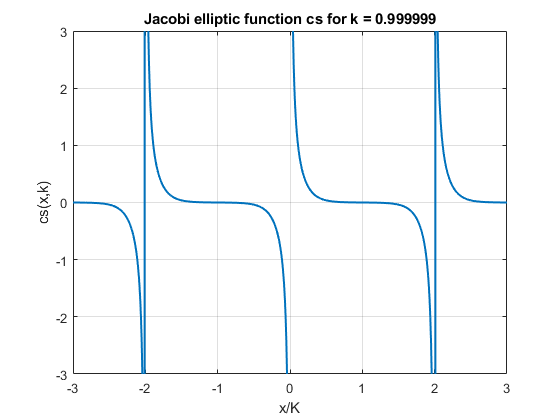

figure
x=-3:0.01:3;
k = 0.999999;
plot(x,JacobiCS(elK(k)*x,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('cs(x,k)')
ylim([-3 3])
title(sprintf('Jacobi elliptic function cs for k = %g',k))
grid on

**Example 2**

figure
X = -6:0.1:6;
M = -2:2:2;
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiCS(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -3 3])
grid on
legend(clg,'Location','Best')

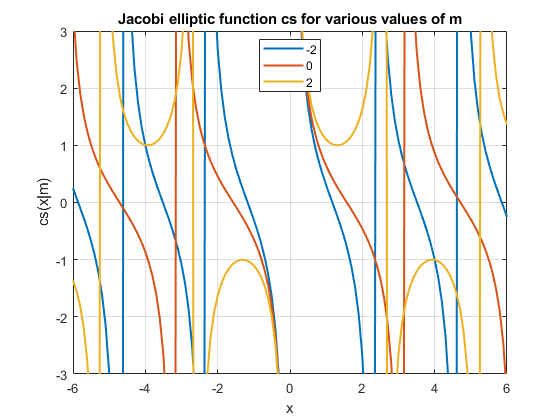

title('Jacobi elliptic function cs for various values of m')
xlabel('x')
ylabel('cs(x|m)')

**Example 3**

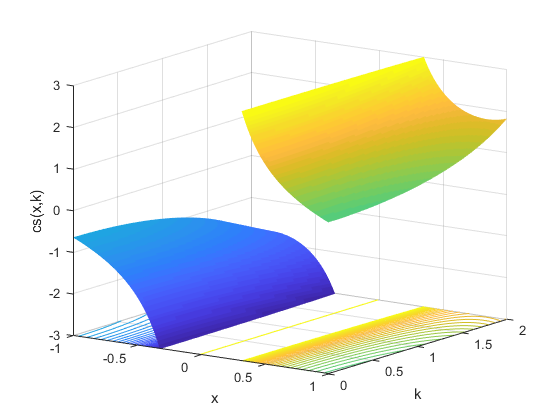

figure
x=-1:0.01:1;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiCS(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.1:3;
caxis([-3 3])
view([35 15]);
xlabel('x')
ylabel('k')
zlabel('cs(x,k)')
zlim([-3 3])
grid on

**Example 4**

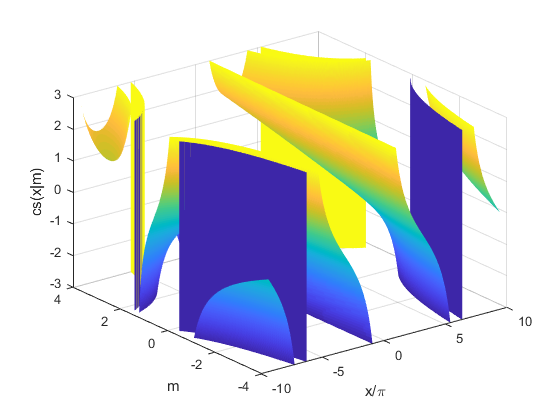

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(pi*X,M,mJacobiCS(X,M),'EdgeColor','none')
view(3)
caxis([-3 3])
xlabel('x/\pi')
ylabel('m')
zlabel('cs(x|m)')
zlim([-3 3])
grid on

**Example 5**

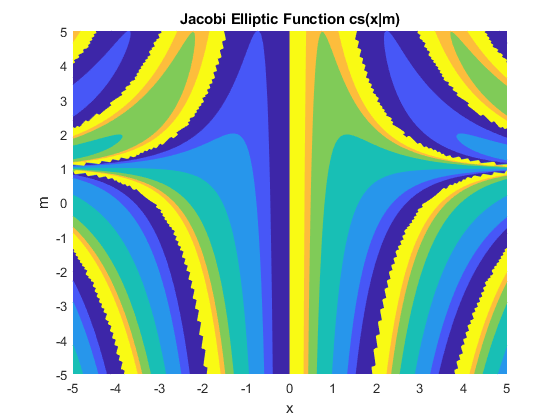

figure
f = @(x,m)mJacobiCS(x,m);
fcontour(f,'Fill','on','MeshDensity',200,'LevelList',-3:1:3)
title('Jacobi Elliptic Function cs(x|m)')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also